# Kinematic Singularities

Author: Keith Chester

E-mail: kchester@wpi.edu

We are looking to define the kinematic sngularities of the following robotic arm:

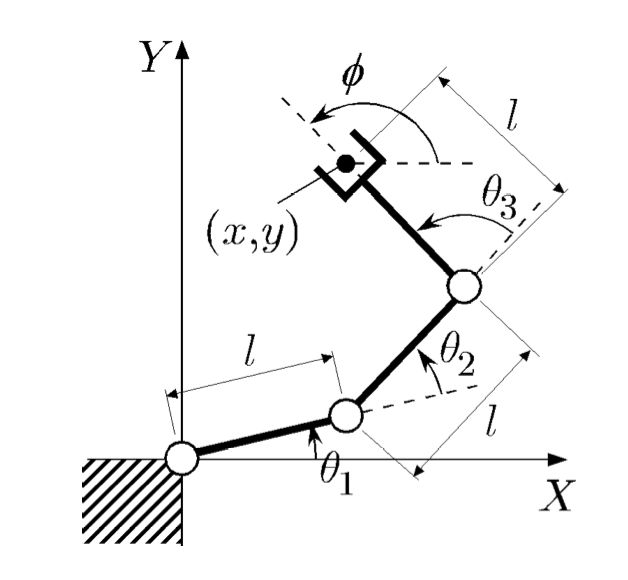

*Figure 1: The robotic arm being analyzed*

Let's look at common singularities.

The first singularity observable is an "overhead" singularity, where the end effector/wrist at the tip of the robot arm crosses over the Y plane. Thus X = 0 for the end effector's (x,y). This overhead singularity is common amongst robotic arms. We have a similar singularity occuring on this robot amongst the x-axis as well - if Y = 0 for the end effector's (x,y). This acts the same as an "overhead" singularity, and is possible as the robot's end-effector can easily reach the X-axis of the first joint.

A planar singularity - often called "elbow" singularities - occurs when at least two joints within the robotic arm become colinear / aligned in space - you lose a degree of freedom (DoF) within the robotic arm, as changing the rotation of one can be canceled by the rotation of the other. This is observed when you see a link in a robotic arm remain "motionless" while other joints move around. This can be beneficial sometimes, but other times leads to pauses in otherwise smooth motion as joints experience unbounded velocities to quickly adjust to a position to continue the desired motion path.

Another common singularity are wrist singularities, but since this robot is a 3DoF robot and does not have a wrist, it is not affected by this. 

Finally, when the arm is fully extended, and all links form a linear arm, we have a boundary of which the robot arm can reach. At each of thse points, we have a boundary singularity.

Now, in order to discover singularities for this 3 degree of freedom arm, we can utilize the Jacobian of the arm to try and identify some.

First, we need to create a DH table to find homogenoues transforms for the arm to work with.

syms l theta1 theta2 theta3
dh_table = { %  theta       d       a    alpha
               [theta1      0       l    0],
               [theta2      0       l    0],
               [theta3      0       l    0],
            };

Using the DH table, we can generate transformation matricies for each link. We can see them here:

A1 = transform_from_dh_row(dh_table, 1, true)

$$A1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & l\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & l\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 = transform_from_dh_row(dh_table, 2, true)

$$A2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & l\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & l\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3 = transform_from_dh_row(dh_table, 3, true)

$$A3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & l\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & l\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

This results in the A1, A2, and A3 homogenous transformation matricies of 

A1 = $\left(\begin{array}{cccc}
\cos \left(\theta_1 \right) & -\sin \left(\theta_1 \right) & 0 & l\,\cos \left(\theta_1 \right)\\
\sin \left(\theta_1 \right) & \cos \left(\theta_1 \right) & 0 & l\,\sin \left(\theta_1 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$

A2 = $\left(\begin{array}{cccc}
\cos \left(\theta_2 \right) & -\sin \left(\theta_2 \right) & 0 & l\,\cos \left(\theta_2 \right)\\
\sin \left(\theta_2 \right) & \cos \left(\theta_2 \right) & 0 & l\,\sin \left(\theta_2 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$

A3 = $\left(\begin{array}{cccc}
\cos \left(\theta_3 \right) & -\sin \left(\theta_3 \right) & 0 & l\,\cos \left(\theta_3 \right)\\
\sin \left(\theta_3 \right) & \cos \left(\theta_3 \right) & 0 & l\,\sin \left(\theta_3 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$

We need, however, to know the transformation matricies all relative to the base 0 frame. To find that, we must multiply through to create each transformaton matrix.

H_0_1 = A1

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & l\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & l\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_2 = simplify(A1*A2)

$$H\_0\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & l\,\left(\cos\left(\theta_{1}+\theta_{2}\right)+\cos\left(\theta_{1}\right)\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & l\,\left(\sin\left(\theta_{1}+\theta_{2}\right)+\sin\left(\theta_{1}\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_3 = simplify(A1*A2*A3)

$$H\_0\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & l\,\left(\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)+\cos\left(\theta_{1}+\theta_{2}\right)+\cos\left(\theta_{1}\right)\right)\\ \sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & l\,\left(\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)+\sin\left(\theta_{1}+\theta_{2}\right)+\sin\left(\theta_{1}\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Thus our transformation matricies are


$$\begin{array}{l}
H_1^0 =\left(\begin{array}{cccc}
\cos \left(\theta_1 \right) & -\sin \left(\theta_1 \right) & 0 & l\,\cos \left(\theta_1 \right)\\
\sin \left(\theta_1 \right) & \cos \left(\theta_1 \right) & 0 & l\,\sin \left(\theta_1 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)\\
H_2^0 =\left(\begin{array}{cccc}
\cos \left(\theta_1 +\theta_2 \right) & -\sin \left(\theta_1 +\theta_2 \right) & 0 & l\,{\left(\cos \left(\theta_1 +\theta_2 \right)+\cos \left(\theta_1 \right)\right)}\\
\sin \left(\theta_1 +\theta_2 \right) & \cos \left(\theta_1 +\theta_2 \right) & 0 & l\,{\left(\sin \left(\theta_1 +\theta_2 \right)+\sin \left(\theta_1 \right)\right)}\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)\\
H_3^0 =\left(\begin{array}{cccc}
\cos \left(\theta_1 +\theta_2 +\theta_3 \right) & -\sin \left(\theta_1 +\theta_2 +\theta_3 \right) & 0 & l\,{\left(\cos \left(\theta_1 +\theta_2 +\theta_3 \right)+\cos \left(\theta_1 +\theta_2 \right)+\cos \left(\theta_1 \right)\right)}\\
\sin \left(\theta_1 +\theta_2 +\theta_3 \right) & \cos \left(\theta_1 +\theta_2 +\theta_3 \right) & 0 & l\,{\left(\sin \left(\theta_1 +\theta_2 +\theta_3 \right)+\sin \left(\theta_1 +\theta_2 \right)+\sin \left(\theta_1 \right)\right)}\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)
\end{array}$$


Now that we have our homogenous transformation matricies for the robot arm's joints, we can explore finding the Jacobian.

The Jacobian for a revolute link is:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} x\left(o_n -o_{i-1} \right)\\
z_i -1
\end{array}\right\rbrack$$


...and the Jacobian for a prismatic link is:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} \\
0
\end{array}\right\rbrack$$


We have an entirely revolute joint robot arm, so we will be only utilizing the former at the moment.

Utilizing functions, whose functions are listed below, we can generate a Jacobian for our given robot arm.

jacobian_from_dh_table(dh_table, true)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -l\,\left(\sigma_{1}+\sin\left(\theta_{1}+\theta_{2}\right)+\sin\left(\theta_{1}\right)\right) & -l\,\left(\sigma_{1}+\sin\left(\theta_{1}+\theta_{2}\right)\right) & -l\,\sigma_{1}\\ l\,\left(\sigma_{2}+\cos\left(\theta_{1}+\theta_{2}\right)+\cos\left(\theta_{1}\right)\right) & l\,\left(\sigma_{2}+\cos\left(\theta_{1}+\theta_{2}\right)\right) & l\,\sigma_{2}\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

This outputs the following Jacobian:


$$\begin{array}{l}
\left(\begin{array}{ccc}
-l\,{\left(\sigma_1 +\mathrm{sin}\left(\theta_1 +\theta_2 \right)+\mathrm{sin}\left(\theta_1 \right)\right)} & -l\,{\left(\sigma_1 +\mathrm{sin}\left(\theta_1 +\theta_2 \right)\right)} & -l\,\sigma_1 \\
l\,{\left(\sigma_2 +\mathrm{cos}\left(\theta_1 +\theta_2 \right)+\mathrm{cos}\left(\theta_1 \right)\right)} & l\,{\left(\sigma_2 +\mathrm{cos}\left(\theta_1 +\theta_2 \right)\right)} & l\,\sigma_2 \\
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
1 & 1 & 1
\end{array}\right)\\
\mathrm{}\\
\mathrm{where}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_1 =\mathrm{sin}\left(\theta_1 +\theta_2 +\theta_3 \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_2 =\mathrm{cos}\left(\theta_1 +\theta_2 +\theta_3 \right)
\end{array}$$


From here, we can decouple the Jacobian, such that


$$J=\left\lbrack \begin{array}{c}
J_{\textrm{linear}} \\
J_{\textrm{angular}} 
\end{array}\right\rbrack$$


Where $J_{\textrm{linear}}$represents the linear velocity component of the Jacobian, and $J_{\textrm{angular}}$ represents the angular velocity component of the Jacobian.

We do this because one easy way to determine the existence of a singularity is to discover if the Jacobian matix has lost rank, representing a loss of a DoF in the current configuration of the arm. This is easy to do by taking the determinant of the Jacobian. Determinants, however, can only be taken from a square matrix. For a 6DoF arm, this is not a concern - the resulting Jacobian is a 6x6 matrix. Here, on our 3 DoF arm, we decoupled the Jacobian to have two smaller 3x3 matrices that we can perform a determinant on.

We could also detect a singularity by utilizing single value decomposition (SVD) on the arm, and determining if the min value returned from this is 0. If so, we have a singularity in that position.

### Functions

#### z_from_transform

Given a transformation, grab the z rotation column and return it as a matrix. This is useful for the Jacobian matrix calculations.

function z = z_from_transform(transform)
    z = transform(1:3, 3);
end

#### translation_from_transform

Given a transformation, isolate the translation column from it. This is useful for the Jacobian matrix calculations.

function o = translation_from_transform(transform)
    o = transform(1:3, 4);
end

#### transformations_from_dh_table

Given a DH table, move through each row and create a series of transformations back to the base (0th frame). This function returns a singular cell of each transformation relative to its frame transformation - where the i-th cell is the $H_i^0$ transformation.

function transforms = transforms_from_dh_table(dh_table, vargin)
    transforms = {};
    transform = 1;
    for row = 1:length(dh_table)
        if nargin == 2
            transforms{end+1} = simplify(transform * transform_from_dh_row(dh_table, row, true));
        else
            transforms{end+1} = transform * transform_from_dh_row(dh_table, row);
        end
        transform = transforms{end};
    end
end

#### jacobian_from_dh

Given a DH table, generate the Jacobian for that DH table. If an additional, second argument is passed if the DH table contains symbolic values, allowing us to do symbolic Jacobian generation instead of a numeric calculation. Extra steps are handled for symbolics - sin vs sind (radians over degrees) and routinely tries to simplify the Jacobian as it is generated.

function j = jacobian_from_dh_table(dh_table, vargin)
    if nargin == 2
        % Initialize our jacobian matrix
        j = sym(zeros(6, length(dh_table)));
        transforms = transforms_from_dh_table(dh_table, true);
    else
        % Initialize our jacobian matrix
        j = zeros(6, length(dh_table));
        transforms = transforms_from_dh_table(dh_table);
    end
    
    o_n = translation_from_transform(transforms{length(dh_table)});
    
    % Prep each row
    for row = 1:length(dh_table)
        row;
        if row == 1
           z_i = [0; 0; 1;];
        else
           transform = transforms{row-1}; 
           z_i = z_from_transform(transform);
        end
        
        if row == 1
           o_i = [0; 0; 0;]; 
        else
           transform = transforms{row-1};
           o_i = translation_from_transform(transform);
        end
        o_i;
        if nargin == 2
            j(1:3, row) = simplify(cross(z_i, o_n-o_i));
        else
            j(1:3, row) = cross(z_i, o_n-o_i);
        end
        cross(z_i, o_n-o_i);
        j(4:6, row) = z_i;
    end
end

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then generates a transform for the given link.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end